Folder = uigetdir('L:\MIGRATED\Lab_Members\Xiaofeng_Dai\2023Fall\W3110_Locus_Tracking');
maskname = uigetfile([Folder,filesep,'*PhaseMask.mat'],'MultiSelect','on');
trackname = uigetfile([Folder,filesep,'*fits.mat'],'MultiSelect','on');

num_file = numel(maskname);
Store_Mask = cell(num_file,1);
Store_Tracks = cell(num_file,1);
parfor i = 1:num_file
    Store_Mask{i} = load([Folder,filesep,maskname{i}]).PhaseMask;
    Store_Tracks{i} = load([Folder,filesep,trackname{i}]).tracks;
end
clear i

### Cell Morphology filter 

**!! set pixel_size**

get morphology plot

pixel_size=49; %65nm per pixel Xindan's Microscope; 49nm Julie's Microscope
num_roi=length(Store_Mask);
Result_Filter=cell(num_roi,1);

%Caculate Cell morphology: length, width, aspect, ratio area
parfor i=1:num_roi
    mask=Store_Mask{i};
    num_cell=max(mask,[],"all");
    result=zeros(num_cell,5);
    result(:,1)=(1:1:num_cell);
    roi_size=size(mask);
    for j=1:num_cell
        singlecell=mask;
        singlecell(singlecell~=j)=0;
        [ind1, ind2]=find(singlecell==j);
        if isempty(ind1)
            continue
        end
        r_up=min(ind1);
        r_up=max(1,r_up-10);
        r_down=max(ind1);
        r_down=min(r_down+10,roi_size(1));
        col_left=min(ind2);
        col_left=max(1,col_left-10);
        col_right=max(ind2);
        col_right=min(roi_size(2),col_right+10);
        singlecell=singlecell(r_up:r_down,col_left:col_right);
        singlecell=singlecell/j;
        ImgProp = regionprops('table',singlecell,'PixelList');
        FeretAna = feretProperties(ImgProp);
        Longaxis=FeretAna.MaxFeretDiameter;
        Shortaxis=FeretAna.MinFeretDiameter;
        aspt_ratio=Longaxis/Shortaxis;
        result(j,2)=Longaxis*pixel_size/1000;            %length of long axis in um
        result(j,3)=Shortaxis*pixel_size/1000;           %length of short axis in nm
        result(j,4)=aspt_ratio;                          %aspect ratio
        result(j,5)=length(ind1)*(pixel_size^2)/1e6;     % size of each cell in um^2
    end
    Result_Filter{i}=result;
end

clear col_left col_right r_up r_down
clear FeretAna i j ImgProp ind1 ind2 Longaxis Shortaxis aspt_ratio num_cell
clear result roi_size singlecell mask

% mkdir([Folder,filesep,'Filter_Results'])
% Cell_Morph.name=repmov;
% Cell_Morph.shape=Result_Filter;
% save([Folder,filesep,'Filter_Results',filesep,'Cell_Morph'],'Cell_Morph')

Result_cat=cat(1,Result_Filter{:});

% Figure plot and saving 
f = figure

f =   Figure (55) with properties:

      Number: 55
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


subplot(2,2,1)
str1 = { ['length = ' sprintf('%.2f ± %.2f', mean(Result_cat(:,2)), std(Result_cat(:,2))) ]};
str2 = {[' ' sprintf('(mean ± std, N = %d)', numel(Result_cat(:,2)))]};
str=append(str1,' \mu','m',str2);
histogram(Result_cat(:,2))
[t,s]=title('Length of Long axis',str);
t.FontSize=13;
s.FontSize=10;

subplot(2,2,3)
% str = { [ 'length = ' sprintf('%.2f ± %.2f nm (mean ± std, N = %d)', mean(Result_cat(:,3)), std(Result_cat(:,3)), numel(Result_cat(:,3))) ] };
str1 = { ['length = ' sprintf('%.2f ± %.2f', mean(Result_cat(:,3)), std(Result_cat(:,3))) ]};
str2 = {[' ' sprintf('(mean ± std, N = %d)', numel(Result_cat(:,3)))]};
str=append(str1,' \mu','m',str2);
histogram(Result_cat(:,3))
[t,s]=title('Length of Short axis',str);
t.FontSize=13;
s.FontSize=10;

subplot(2,2,2)
% str = { [ ' ' sprintf('%.2f ± %.2f (mean ± std, N = %d)', mean(Result_cat(:,4)), std(Result_cat(:,4)), numel(Result_cat(:,4))) ] };
str1 = { [' ' sprintf('%.2f ± %.2f', mean(Result_cat(:,4)), std(Result_cat(:,4))) ]};
str2 = {[' ' sprintf('(mean ± std, N = %d)', numel(Result_cat(:,4)))]};
str=append(str1,str2);
histogram(Result_cat(:,4))
[t,s]=title('Aspect Ratio',str);
t.FontSize=13;
s.FontSize=10;

subplot(2,2,4)
% str = { [ 'Area = ' sprintf('%.2e ± %.2e nm^2 (mean ± std, N = %d)', mean(Result_cat(:,5)), std(Result_cat(:,5)), numel(Result_cat(:,5))) ] };
str1 = { ['length=' sprintf('%.2f ± %.2f', mean(Result_cat(:,5)), std(Result_cat(:,5))) ]};
str2 = {[' ' sprintf('(mean ± std, N = %d)', numel(Result_cat(:,5)))]};
str=append(str1,' {\mu}','m^2',str2);
histogram(Result_cat(:,5))
[t,s]=title('Area of cell',str);
s.FontSize=10;
t.FontSize=13;

f.Position = [100 100 1080 800];

clear s t str1 str2 str

mkdir(strcat(Folder,filesep,'Results_Filter'))

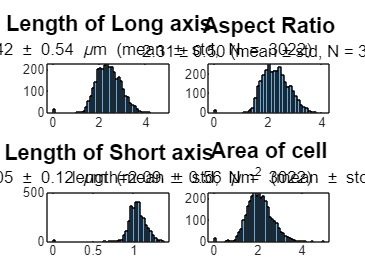

saveas(f,strcat(Folder,filesep,'Results_Filter',filesep,'Cell Morphology.png'))

save(strcat(Folder,filesep,'Results_Filter',filesep,'Cell Morphology.mat'),'Result_cat')

clear f

**!! Set boundary conditions, upper and lower bound**

**get boolean value representing cell passing filter**

single filter

% set boundary condition
Bndry_condtion=1;       % 1-->long axis; 2-->short axis; 3-->aspect ratio ; 4-->area 
%% specify lower bound and upper bound by distribution
% low_bd=mean_table(Bndry_condtion,3);
% up_bd=mean_table(Bndry_condtion,4);
%% set lower bound and upper bound by hand
low_bd=1.6;
up_bd=2.5;

Filter_Index=cell(num_roi,1);
for i=1:num_roi
    buff=Result_Filter{i};
    result=zeros(length(buff(:,1)),2);
    result(:,1)=(1:1:length(buff(:,1)));
    for j=1:length(buff(:,1))
        if buff(j,Bndry_condtion+1)>low_bd && buff(j,Bndry_condtion+1)<up_bd
            result(j,2)=1;
        end
    end
    Filter_Index{i}=result;
end

clear i j buff result

deter=Result_cat(:,Bndry_condtion+1);
deter(deter<=low_bd)=0;
deter(deter>=up_bd)=0;
Remaining_ratio=length(deter(deter~=0))/length(deter)

Remaining_ratio = 0.5321

clear deter 

% save results
Result_LengthFilter.boundary = [low_bd,up_bd];
Result_LengthFilter.ratio=Remaining_ratio;
Result_LengthFilter.index=Filter_Index;

save([Folder,filesep,'Results_Filter',filesep,'Length_Filter'],'Result_LengthFilter')
clear low_bd up_bd

### Locus Filter

clearvars -except Folder Store_Tracks Store_Mask pixel_size

set parameters

1) calculate number of locus in each cell

2) calculate relative position of each locus relative to cell pole

3) calculate circularity of trajactory from each locus to determin transition from old pole to new pole

**!! set up threshold to determin cluster**

Thres=50 %% # localization threshold to determine a cluster, minimum step

Thres = 50

num_roi=length(Store_Tracks);
Result_LocusNum=cell(num_roi,1);
Result_LocusPos=cell(num_roi,1);
Store_newTracks=cell(num_roi,1);
parfor i=1:num_roi
    mask=Store_Mask{i};
    tracks=Store_Tracks{i};
    num_cell=max(mask,[],"all");
    roi_size=size(mask);
    result=zeros(num_cell,2);
    result(:,1)=(1:1:num_cell);
    newTrack=cell(num_cell,1);
    result_cluster_com=cell(num_cell,1);
    for j=1:num_cell
        singlecell=mask;
        singlecell(singlecell~=j)=0;
        [ind1, ind2]=find(singlecell==j);
        r_up=min(ind1);
        r_up=max(1,r_up-10);
        r_down=max(ind1);
        r_down=min(r_down+10,roi_size(1));
        col_left=min(ind2);
        col_left=max(1,col_left-10);
        col_right=max(ind2);
        col_right=min(roi_size(2),col_right+10);
        singlecell=singlecell(r_up:r_down,col_left:col_right);
        singlecell=singlecell/j;
        ImgProp = regionprops('table',singlecell,'PixelList');
        FeretAna = feretProperties(ImgProp);
        cellpole=FeretAna.MaxFeretDiameterEndpoints;
        cellpole=cell2mat(cellpole);
        
        cell_track=tracks(tracks(:,5)==j,:);
        
        if isempty(cell_track)
            continue
        end
        
        idx=dbscan(cell_track(:,2:3),1.2,10);        
%         %%% scatter visulization 
%         figure
%         color = jet(length(unique(idx)));
%         imshow(singlecell,[])
%         hold on
%         gscatter(cell_track(:,3)-col_left+1,cell_track(:,2)-r_up+1,idx,color(:,:),'o',1.2)
%         legend Location northeastoutside
%         %%%
        
        Num_cluster=unique(idx);
        Num_cluster(Num_cluster<0)=[];
        
        for k=1:length(Num_cluster)
            index=Num_cluster(k);
            count=find(idx==index);
            if length(count)<Thres
                Num_cluster(k)=-5;
            end
        end
        Num_cluster(Num_cluster<0)=[];
        num_loci=length(Num_cluster);
        result(j,2)=num_loci;
        
        
        %% link break from same locus by result from spatial cluster
        buff=cell(length(Num_cluster),1);
        for m=1:length(Num_cluster)
            ind=Num_cluster(m);
%             test=cell_track(idx==m,:);
            test=cell_track(idx==ind,:);
            ind2=test(1,4);
            test(:,4)=ind2;
            buff{m}=test;
        end
        buff=cat(1,buff{:});
        newTrack{j}=buff;
        
        %% for each cluster, 1)calculate distance from cell pole; 2)measuere cirularity 
        result_cluster=zeros(length(Num_cluster),3);
        for o=1:length(Num_cluster)
            ind=Num_cluster(o);
            each_clus=cell_track(idx==ind,:);
            each_clus(:,3)=each_clus(:,3)-col_left+1;
            each_clus(:,2)=each_clus(:,2)-r_up+1;
            
            center_row=mean(each_clus(:,2));
            center_col=mean(each_clus(:,3));
            cellpole1=cellpole(1,:);
            cellpole2=cellpole(2,:);
            dis1=sqrt((center_row-cellpole1(2))^2+(center_col-cellpole1(1))^2);
            dis2=sqrt((center_row-cellpole2(2))^2+(center_col-cellpole2(1))^2);
            dis2pole=min(dis1,dis2)*pixel_size; %% distance to cellpole in nm
            
            coord_bnd=boundary(each_clus(:,2),each_clus(:,3),0.1);
            %% use poly2mask to get shape of this region
%             locus_region=poly2mask(each_clus(coord_bnd,2),each_clus(coord_bnd,3),roi_size(1),roi_size(2));
            locus_region=poly2mask((each_clus(coord_bnd,2)-min(each_clus(coord_bnd,2)))*10+1,(each_clus(coord_bnd,3)-min(each_clus(coord_bnd,3)))*10+1, ...
                                    ceil((max(each_clus(coord_bnd,2)*10)-min(each_clus(coord_bnd,2)*10))*1.5)+10,ceil((max(each_clus(coord_bnd,3)*10)-min(each_clus(coord_bnd,3)*10))*1.5)+10);
            ImgProp = regionprops('table',locus_region,'PixelList');
            
            % in case multiple line in ImgProp
            if height(ImgProp)>1
                aa = height(ImgProp);
                dd = zeros(aa,1);
                for bb = 1:aa
                    cc = ImgProp(bb,:);
                    dd(bb) = length(cc.PixelList{:});
                end
                ee = find(dd==max(dd));
                ImgProp = ImgProp(ee,:);
            end
            %
            
            % if height(ImgProp.PixelList{1})>1
            %     FeretAna = feretProperties(ImgProp);
            %     eclps_ratio=FeretAna.MaxFeretDiameter/FeretAna.MinFeretDiameter;
            % else
            %     eclps_ratio=[];
            % end

            try
                FeretAna = feretProperties(ImgProp);
                eclps_ratio=FeretAna.MaxFeretDiameter/FeretAna.MinFeretDiameter;
                result_cluster(o,1)=each_clus(1,4);
                result_cluster(o,2)=dis2pole;
                result_cluster(o,3)=eclps_ratio;
            catch
                result_cluster(o,:)=[];
            end
        end
        result_cluster_com{j}=result_cluster;
        
        
    end
    Result_LocusNum{i}=result;
    Store_newTracks{i}=cat(1,newTrack{:});
    Result_LocusPos{i}=cat(1,result_cluster_com{:});
end

clear buff cell_track cellpole cellpole1 cellpole2 center_col center_row
clear col_left col_right coord_bnd count dis1 dis2 dis2pole each_clus eclps_ratio
clear FeretAna i idx ImgProp ind ind1 ind2 index j k locus_region
clear m mask newTrack num_cell Num_cluster num_loci num_roi o r_down r_up
clear result roi_size singlecell test tracks result_cluster result_cluster_com
clear aa bb cc dd

Locus info visulization

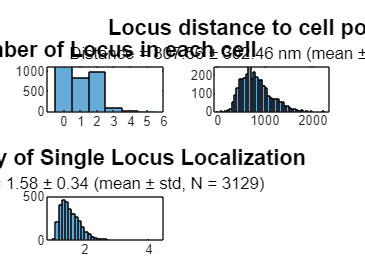

% plot result from calculation above 
Result_plot=cat(1,Result_LocusNum{:});
edges = (-0.5:1:max(Result_plot(:,2))+0.5);
f= figure;
nexttile
histogram(Result_plot(:,2),edges);
t = title('Number of Locus in each cell');
t.FontSize=13;
xlim([-1 max(Result_plot(:,2))+1])
xticks(edges+0.5)
save(strcat(Folder,filesep,'Results_Filter',filesep,'Locus_num.mat'),'Result_plot')

Result_plot=cat(1,Result_LocusPos{:});
nexttile
str1 = { ['Distance = ' sprintf('%.2f ± %.2f', mean(Result_plot(:,2)), std(Result_plot(:,2))) ]};
str2 = {[' ' sprintf('(mean ± std, N = %d)', numel(Result_plot(:,2)))]};
str=append(str1,' n','m',str2);
histogram(Result_plot(:,2));
[t, s] = title('Locus distance to cell pole (nm)',str);
t.FontSize=13;
s.FontSize=10;

nexttile
str1 = { ['Ratio = ' sprintf('%.2f ± %.2f', mean(Result_plot(:,3)), std(Result_plot(:,3))) ]};
str2 = {[' ' sprintf('(mean ± std, N = %d)', numel(Result_plot(:,2)))]};
str=append(str1,str2);
histogram(Result_plot(:,3));
[t, s] = title('Circulirity of Single Locus Localization', str);
t.FontSize=13;
s.FontSize=10;

f.Position = [100 100 1080 800];

clear edges t s str1 str2 str

save(strcat(Folder,filesep,'Results_Filter',filesep,'Locus_info.mat'),'Result_plot')
saveas(f,strcat(Folder,filesep,'Results_Filter',filesep,'Locus_info.png'))

clear result_plot
% save results
newTracks.localization=Store_newTracks; 
Locus_Filter.number=Result_LocusNum;
Locus_Filter.position=Result_LocusPos;
save([Folder,filesep,'Results_Filter',filesep,'newTracks'],'newTracks')
save([Folder,filesep,'Results_Filter',filesep,'Locus_Filter'],'Locus_Filter')

### Get filtered results and stored as trajactory by trakcs

clearvars -except Folder pixel_size

**!! set up filter parameter regarding locus**

% set up filter parameter regarding locus 
% range of locus number, e.g. [1,2] --> >=1 & <=2; [1,1] --> >=1 &<=1, which is 1
Thres_LocNum=[1,4];  
Thres_dis2pol=[250, 1800];
Thres_circle=[1, 3];

Loc_Thres.LocNum = Thres_LocNum;
Loc_Thres.dis2pol = Thres_dis2pol;
Loc_Thres.circle = Thres_circle;
save([Folder,filesep,'Results_Filter',filesep,'Locus_Filter_Range'],'Loc_Thres')
clear Loc_Thres

Load filter and tracks, leave tracks that pass all filters

% load filter results
Folder=[Folder,filesep,'Results_Filter'];
newTracks=load([Folder,filesep,'newTracks.mat']).newTracks.localization;
buff=load([Folder,filesep,'Length_Filter.mat']);
buff=buff.Result_LengthFilter;
Filter_Length=buff.index;
buff=load([Folder,filesep,'Locus_Filter.mat']);
buff=buff.Locus_Filter;
Filter_LocusNum=buff.number;
Filter_LucusPos=buff.position;
clear buff

% get trajectory pass all filters
num_roi=length(newTracks);
Traj_after_filter=cell(num_roi,1);
% Filter_result=cell(num_roi,1)
for i=1:num_roi
    each_length=Filter_Length{i};
    each_numloc=Filter_LocusNum{i};
    ind1=each_length(:,2)==1;
    cell_ind1=each_length(ind1,1);
    ind2=each_numloc(:,2)>=Thres_LocNum(1)&each_numloc(:,2)<=Thres_LocNum(2);
    cell_ind2=each_length(ind2,1);
    [cell_ind]=intersect(cell_ind1,cell_ind2);
    
    each_locpos=Filter_LucusPos{i};
    ind1=each_locpos(:,2)<=Thres_dis2pol(2)&each_locpos(:,2)>=Thres_dis2pol(1);
    traj_ind1=each_locpos(ind1,1);
    ind2=each_locpos(:,3)<=Thres_circle(2)&each_locpos(:,3)>=Thres_circle(1);
    traj_ind2=each_locpos(ind2,1);
    [traj_ind]=intersect(traj_ind1,traj_ind2);
    
    each_newTracks=newTracks{i};
    filter_by_track=cell(length(traj_ind),1);
    for j=1:length(traj_ind)
        buff=traj_ind(j);
        ind=find(each_newTracks(:,4)==buff);
        filter_by_track{j}=ind;
    end
    filter_by_track=cat(1,filter_by_track{:});
    filter_by_cell=cell(length(cell_ind),1);
    for k=1:length(cell_ind)
        buff=cell_ind(k);
        ind=find(each_newTracks(:,5)==buff);
        filter_by_cell{k}=ind;
    end
    filter_by_cell=cat(1,filter_by_cell{:});
    track_ind=intersect(filter_by_cell,filter_by_track);
    track_after_filter=each_newTracks(track_ind,:);
    Traj_after_filter{i}=track_after_filter;
end

clear buff cell_ind cell_ind1 cell_ind2 each_length
clear each_numloc each_locpos each_newTracks 
clear filter_by_track filter_by_cell i ind ind1 ind2 j k
clear track_after_filter track_ind traj_ind traj_ind1 traj_ind2

save([Folder,filesep,'Tracks_passFilter'],'Traj_after_filter')